%1. Define equations for the model and load timeseries data

syms  Ms(t) Me(t) Mi(t) Hs(t) He(t) Hi(t) Hr(t) Hit(t)

syms lambda beta_m mu_m theta_m mu_h beta_h theta_h...
    gamma_h

%pulse(t)=1;
H=Hs+He+Hi+Hr;
M=Ms+Me+Mi;
ode1 = diff(Ms) == lambda - beta_m*Hi*Ms/H - (mu_m)*Ms;
ode2 = diff(Me) == beta_m*Hi*Ms/H - (theta_m+mu_m)*Me;
ode3 = diff(Mi) == theta_m*Me - mu_m*Mi;
ode4 = diff(Hs) == -beta_h*Mi*Hs/M + (He+Hi+Hr)*mu_h;
ode5 = diff(He) == beta_h*Mi*Hs/M - (theta_h+mu_h)*He;
ode6 = diff(Hi) == theta_h*He - (gamma_h+mu_h)*Hi;
ode7 = diff(Hr) == gamma_h*Hi - mu_h*Hr;
ode8 = diff(Hit) == theta_h*He;
odes=[ode1; ode2 ;ode3; ode4; ode5 ;ode6; ode7; ode8];
vars=[Hit Hi Me Hr Hs He Ms Mi];
opts = odeset('NonNegative',1:8);

%2. Data preparation

load Range7.mat
load('DataBello_full.mat');
ydata=DataBello.cases(153:233)';
xdata=linspace(0,length(ydata)-1,length(ydata));
ydata2=ydata;
for i=1:length(ydata)
ydata2(i)=sum(ydata(1:i));
end

%3.Analisis de sensibilidad

%3.1. Data prep

[T,~]=gsua_dpmat(odes,vars,[0 80],'7m','output',1,'opt',opts,'Range',Range);

Introduce ranges in the following order: 


$$ans(t) = \left(\begin{array}{cccccccccccccccc} \mathrm{Hit}\left(t\right) & \mathrm{Hi}\left(t\right) & \mathrm{Me}\left(t\right) & \mathrm{Hr}\left(t\right) & \mathrm{Hs}\left(t\right) & \mathrm{He}\left(t\right) & \mathrm{Ms}\left(t\right) & \mathrm{Mi}\left(t\right) & \beta_{h} & \beta_{m} & \gamma_{h} & \lambda & \mu_{h} & \mu_{m} & \theta_{h} & \theta_{m} \end{array}\right)$$

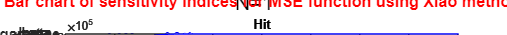

Error using matlab.graphics.axis.Axes/set
Error setting property 'Position' of class 'Axes':
Width and height must be greater than or equal to 0

Error in suptitle (line 86)
        set(h(i),'position',pos);

Error in gsua_plot (<a href="

T.Properties.CustomProperties.output = 1;
M = gsua_dmatrix(T,100);

ynom = gsua_eval(T.Nominal,T);

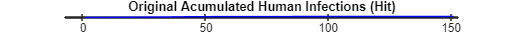

clf
plot(cumsum(ydata),'b')
title('Original Acumulated Human Infections (Hit)')
xlabel('Weeks')
ylabel('Cases')

savefig('iteration1/figures/NominalValues.fig')

%3.2. Sensibility analysis

Tsa = gsua_sa(M,T,'parallel', false, 'SensMethod', 'Xiao', 'ynom', ynom);

Progress: 7%
Estimated processing time (h:m:s): 0:0:8
Remaining time (h:m:s): 0:0:8
Elapsed time (h:m:s): 0:0:0
Estimated stop time (h:m:s): 18:17:20
Number of simulations: 750
Progress: 14%
Estimated processing time (h:m:s): 0:0:9
Remaining time (h:m:s): 0:0:7
Elapsed time (h:m:s): 0:0:1
Estimated stop time (h:m:s): 18:17:20
Number of simulations: 750
Progress: 20%
Estimated processing time (h:m:s): 0:0:9
Remaining time (h:m:s): 0:0:7
Elapsed time (h:m:s): 0:0:1
Estimated stop time (h:m:s): 18:17:20
Number of simulations: 750
Progress: 27%
Estimated processing time (h:m:s): 0:0:8
Remaining time (h:m:s): 0:0:6
Elapsed time (h:m:s): 0:0:2
Estimated stop time (h:m:s): 18:17:20
Number of simulations: 750
Progress: 34%
Estimated processing time (h:m:s): 0:0:9
Remaining time (h:m:s): 0:0:6
Elapsed time (h:m:s): 0:0:3
Estimated stop time (h:m:s): 18:17:20
Number of simulations: 750
Progress: 40%
Estimated processing time (h:m:s): 0:0:8
Remaining time (h:m:s): 0:0:5
Elapsed time (h:m:s): 0:0:

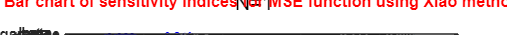


gsua_plot('Bar',Tsa,Tsa.STi)
savefig('iteration1/figures/SensibilityAnalisis.fig')


%3.3. Confiabilidad

c = sum(Tsa.Si)/sum(abs(Tsa.Si))

c = 0.9771

%3.4 Fixing parameters

%According to the sensitivity analysis, we will fix the 4 parameters with
%the lower sensitivity indexes (with the nominal values).

%These are He0 and Me0, añadir Ms0
%vars=[Hit Hi Me Hr Hs He Ms Mi];
vars=[Hit Hi He Me Hr Hs Ms Mi];
HeO = T.Nominal('He0');

RangeTemp = Range; 
Range(3,:) = HeO; 

Range = 1.0e+06 *

    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.6000    0.6000
    0.0001    0.0001
    0.0000    0.0001
         0    1.2000
         0    0.0001
         0    0.0000
         0    0.0000


Range(4:8,:) = [RangeTemp(4,:); RangeTemp(5,:); RangeTemp(8,:)];

[T,~]=gsua_dpmat(odes,vars,[0 150],'7m','output',1,'opt',opts,'Range',Range);

Introduce ranges in the following order: 


$$ans(t) = \left(\begin{array}{cccccccccccccccc} \mathrm{Hit}\left(t\right) & \mathrm{Hi}\left(t\right) & \mathrm{He}\left(t\right) & \mathrm{Ms}\left(t\right) & \mathrm{Me}\left(t\right) & \mathrm{Mi}\left(t\right) & \mathrm{Hr}\left(t\right) & \mathrm{Hs}\left(t\right) & \beta_{h} & \beta_{m} & \gamma_{h} & \lambda & \mu_{h} & \mu_{m} & \theta_{h} & \theta_{m} \end{array}\right)$$

T.Properties.CustomProperties.output = 1;
M = gsua_dmatrix(T,100);
ynom = gsua_eval(T.Nominal,T);
save('iteration1/values/T.mat','T')

%3.5. Parameter estimation

%(takes a lot of time)

opt = optimoptions('lsqcurvefit','UseParallel',true,'Display','iter');
[T7,res] = gsua_pe(T,xdata,ydata2,'N',100,'opt',opt); %mover N ( 100 buena, 50 aceptable, 10 :( )

Generating a valid matrix for estimations
Estimation 1


save('iteration1/values/Results7.mat','T7','res','xdata','ydata2')

%3.6 Identifiability analysis 
%Cogemos el 30 % para solo tomar una de las familias
th = sum(res<res(1)*1.3)
y7 = gsua_eval(T7.Estlsqc(:,1:th),T7,xdata,ydata2);
savefig('iteration1/figures/curves.fig')

bestest = y7(1,:);
trend = [bestest(1),bestest(2:end)-bestest(1:end-1)];
plot(trend,'b')
hold on
plot(diff(ydata2),'r')
title('Estimated vs Real Weekly Infections')
xlabel('Weeks')
ylabel('Cases')
legend({'Estimated','Real'})
savefig('iteration1/figures/EstimatedvsReal.fig')

T7.Nominal = T7.Estlsqc(:,1);
%res : funciones de costo
th = sum(res<res(1)*1.3) % threshold, cambiar el 1.01
%th = 476 %el parametro que habia dado el profe, a nosotros nos da 1????

T7_ia = gsua_ia(T7,T7.Estlsqc(:,1:th), false, true); 
savefig('iteration1/figures/CorrelationsDiag.fig')

Segunda iteracion de los calculos

%5.1 Aumentamos los rangos de thetaH
T.Range('theta_h',1) = 0;
T.Range('lambda',1) = 800;
T.Range('gamma_h',1) = 0;


%Realizamos analisis otra vez
Tsa = gsua_sa(M,T,'parallel', false, 'SensMethod', 'Xiao', 'ynom', ynom);

gsua_plot('Bar',Tsa,Tsa.STi)
savefig('iteration2/figures/SensibilityAnalisis.fig')


% Confiabilidad

c = sum(Tsa.Si)/sum(abs(Tsa.Si))
save('iteration2/values/T.mat','T')

%5.2 estimation
opt = optimoptions('lsqcurvefit','UseParallel',true,'Display','iter');
[T7_1,res_1] = gsua_pe(T,xdata,ydata2,'N',100,'opt',opt); 
save('iteration2/values/Results7.mat','T7_1','res_1','xdata','ydata2')

%5.2 Identifiability analysis 
%Como hay solo una familia se cogen todas las estimaciones
th_1 = sum(res_1<res_1(1)*1.15)
y7_1 = gsua_eval(T7_1.Estlsqc(:,1:end),T7_1,xdata,ydata2);
savefig('iteration2/figures/curves.fig')

bestest_1 = y7_1(1,:);
trend = [bestest_1(1),bestest_1(2:end)-bestest_1(1:end-1)];
plot(trend,'b')
hold on
plot(diff(ydata2),'r')
title('Estimated vs Real Weekly Infections')
xlabel('Weeks')
ylabel('Cases')
legend({'Estimated','Real'})
savefig('iteration2/figures/EstimatedvsReal.fig')

T7_1.Nominal = T7_1.Estlsqc(:,1);
%res : funciones de costo

T7_1ia = gsua_ia(T7_1,T7_1.Estlsqc(:,1:end), false, true); 
savefig('iteration2/figures/CorrelationsDiag.fig')

Tercera Iteracion

%Fijamos Hs_0


%vars=[Hit Hi He Ms Me Hr Hs Mi];
vars=[Hit Hi He Ms Me Hs Hr Mi];
HsO = T7_1.Nominal('Hs0'); 

RangeTemp = Range;
Range(6,:) = HsO;
Range(7,:) = RangeTemp(6,:);

[T,~]=gsua_dpmat(odes,vars,[0 150],'7m','output',1,'opt',opts,'Range',Range);
T.Properties.CustomProperties.output = 1;
M = gsua_dmatrix(T,100);

%5.2 estimation
opt = optimoptions('lsqcurvefit','UseParallel',false,'Display','iter');
[T7_2,res_2] = gsua_pe(T,xdata,ydata2,'N',100,'opt',opt); 
save('iteration3/values/Results7.mat','T7_2','res_2','xdata','ydata2')

%5.2 Identifiability analysis 
th_2 = sum(res_2<res_2(1)*1.02)
y7_2 = gsua_eval(T7_2.Estlsqc(:,1:th_2),T7_2,xdata,ydata2);
savefig('iteration3/figures/curves.fig')

bestest_2 = y7_2(1,:);
trend = [bestest_2(1),bestest_2(2:end)-bestest_2(1:end-1)];
plot(trend,'b')
hold on
plot(diff(ydata2),'r')
title('Estimated vs Real Weekly Infections')
xlabel('Weeks')
ylabel('Cases')
legend({'Estimated','Real'})
savefig('iteration3/figures1/EstimatedvsReal.fig')

T7_2.Nominal = T7_2.Estlsqc(:,1);
%res : funciones de costo
th_2 = sum(res_2<res_2(1)*1.02) % threshold, cambiar el 1.01
%th = 476 %el parametro que habia dado el profe, a nosotros nos da 1????

T7_2 = gsua_ia(T7_2,T7_2.Estlsqc(:,1:th_2), false, true); 
savefig('iteration3/figures/Correlations.fig')
save('iteration3/values/T.mat','T')

%4.4 Uncertainty analysis

%analisis de incertidumbre con T7_2. veamos que las curvas hagan una banda 
%al lado de los datos que estamos estimando. Si la banda es chevere,
%terminamos, si no, fijar algun parametro. 

Ua = gsua_ua(M, T7_2, 'parallel', false, 'ynom',ydata2);
savefig('iteration3/figures/Montecarlo.fig')

Cuarta Iteracion

%Fijamos Beta_h


Range(9,:) = T7_3.Nominal('beta_h');
[T,~]=gsua_dpmat(odes,vars,[0 150],'7m','output',1,'opt',opts,'Range',Range);
T.Properties.CustomProperties.output = 1;
M = gsua_dmatrix(T,100);

%Realizamos analisis otra vez
Tsa = gsua_sa(M,T,'parallel', false, 'SensMethod', 'Xiao', 'ynom', ynom);

gsua_plot('Bar',Tsa,Tsa.STi)
savefig('iteration4/figures/SensibilityAnalisis.fig')


% Confiabilidad

c = sum(Tsa.Si)/sum(abs(Tsa.Si))

%5.2 estimation
opt = optimoptions('lsqcurvefit','UseParallel',false,'Display','iter');
[T7_3,res_3] = gsua_pe(T,xdata,ydata2,'N',100,'opt',opt); 
save('iteration4/values/Results7.mat','T7_3','res_3','xdata','ydata2')

%5.2 Identifiability analysis 
th_3 = sum(res_3<res_3(1)*1.02)
y7_3 = gsua_eval(T7_3.Estlsqc(:,1:th_3),T7_3,xdata,ydata2);
savefig('iteration4/figures/curves.fig')

bestest_3 = y7_3(1,:);
trend = [bestest_3(1),bestest_3(2:end)-bestest_3(1:end-1)];
plot(trend,'b')
hold on
plot(diff(ydata2),'r')
title('Estimated vs Real Weekly Infections')
xlabel('Weeks')
ylabel('Cases')
legend({'Estimated','Real'})
savefig('iteration4/figures/EstimatedvsReal.fig')

T7_3.Nominal = T7_3.Estlsqc(:,1);
%res : funciones de costo
th_3 = sum(res_3<res_3(1)*1.02) % threshold, cambiar el 1.01
%th = 476 %el parametro que habia dado el profe, a nosotros nos da 1????

T7_3 = gsua_ia(T7_3,T7_3.Estlsqc(:,1:th_3), false, true); 
savefig('iteration4/figures/Correlations.fig')

%Uncertainty analysis

%analisis de incertidumbre con T7_3. veamos que las curvas hagan una banda 
%al lado de los datos que estamos estimando. Si la banda es chevere,
%terminamos, si no, fijar algun parametro. 

Ua = gsua_ua(M, T7_3, 'parallel', false, 'ynom',ydata2);
savefig('iteration4/figures/Montecarlo.fig')